# Goertzel Probabilty of Detection

clear                                  % Clear all data stored in variables
Am = 1;                                % 1V Amplitude     
SR = 48000;                            % 48 KHz Smapling Rate
f0 = 20e+3;                            % 20 KHz
duration = (127/SR);                   % ~ 2.6 ms 
t = 0:1/SR:duration;                   % Time Vector

sinusPulse = Am*sin(2*pi*f0*t);  % Signal with multiple frequencies

mySNR = -30:30;
threshold = 300;

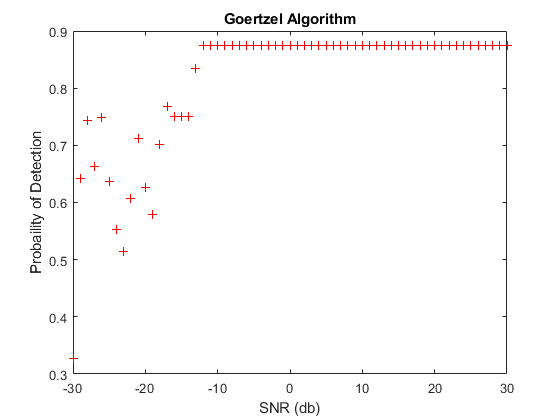

snrValues(sinusPulse,mySNR,threshold,f0,SR)

function snrValues(yourSignal,snr,threshold,f0,SR) 
   for i = 1:length(snr)
       for j = 1:100
           Pd_buff(100) = 0;
           yourSignal = awgn(yourSignal,snr(i));
           N = length(yourSignal);
           Magnitude(N) = 0;
           k = round(0.5 + N*f0/SR);
           w = 2*pi*k/N;
           cosine = cos(w);
           coeff = 2*cosine;
           Q2 = 0;
           Q1 = 0;
           for k = 1:N
               Q0 = yourSignal(k) + coeff*Q1 - Q2;
               Q2 = Q1;
               Q1 = Q0;
               Magnitude(k) = sqrt(Q1*Q1 + Q2*Q2 - Q1*Q2*coeff);
           end
           Pd_buff(j) = sum(Magnitude > threshold)/N;
       end
       Pd = sum(Pd_buff)/100;
       plot(snr(i),Pd,'r+');
       hold on
       title('Goertzel Algorithm')
       xlabel('SNR (db)')
       ylabel('Probaility of Detection')
   end
   hold off
end